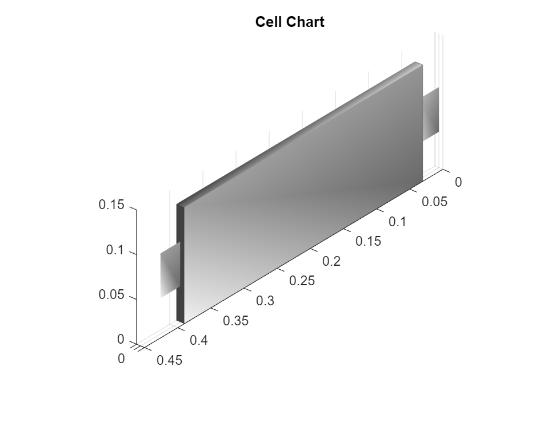

import simscape.battery.builder.*

batteryCell = Cell();
cellGeometry = PouchGeometry();
cellGeometry.Length = simscape.Value(0.36, "m");
cellGeometry.Height = simscape.Value(0.13, "m");
cellGeometry.TabWidth = simscape.Value(0.05, "m");
cellGeometry.TabLocation = "Opposed";
batteryCell.Geometry = cellGeometry;

batteryCell.Mass = simscape.Value(0.8,"kg");
batteryCell.CellModelOptions.CellModelBlockPath = 'batt_lib/Cells/Battery Equivalent Circuit';
batteryCell.CellModelOptions.BlockParameters.ThermalModel = "LumpedThermalMass";
batteryCell.CellModelOptions.BlockParameters.RCPairs = "rc1";

f = uifigure("Color", "white");
moduleChart = BatteryChart(Parent = f, Battery = batteryCell);
title(moduleChart, "Cell Chart");

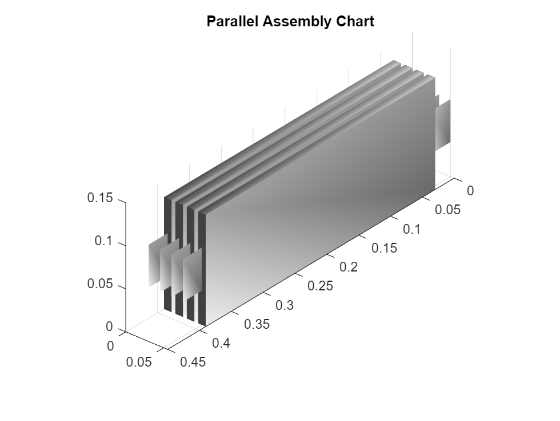

parallelAssembly = ParallelAssembly(...
    NumParallelCells = 4, ...
    Cell = batteryCell, ...
    Topology = "SingleStack", ...
    InterCellGap = simscape.Value(0.005, "m"));


f = uifigure("Color", "white");
moduleChart = BatteryChart(Parent = f, Battery = parallelAssembly);
title(moduleChart, "Parallel Assembly Chart");

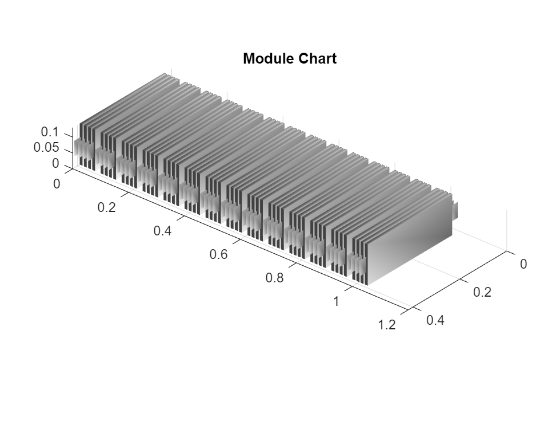

module = Module(...
    ParallelAssembly = parallelAssembly, ...
    NumSeriesAssemblies = 14, ... 
    InterParallelAssemblyGap = simscape.Value(0.02, "m"));

module.ModelResolution='Grouped';
module.SeriesGrouping=[4 5 5];


f = uifigure("Color", "white");
moduleChart = BatteryChart(Parent = f, Battery = module);
title(moduleChart, "Module Chart")

moduleassembly = ModuleAssembly(Module=module);
moduleassembly.CoolantThermalPath="CellBasedThermalResistance";
moduleassembly.CoolingPlate='Bottom';
moduleassembly.CoolingPlateBlockPath = "batt_lib/Thermal/Edge Cooling";

% remove existing library files if exist
proj = matlab.project.rootProject;
DirPath = proj.RootFolder + '\Lib'
cd(DirPath)
files1 = dir(fullfile(pwd, ['+pouch', '*']));
if ~isempty(files1)
    rmdir('+*','s');     
end
files2 = dir(fullfile(pwd, ['pouch', '*']));
if ~isempty(files2)
    delete('pouch*');
end

import simscape.battery.builder.*
% buildBattery(module,"LibraryName","moduleExample");
buildBattery(moduleassembly,"LibraryName","pouchPackExample",...
    'MaskInitialTargets',"VariableNames","MaskParameters","VariableNames");

Generating Simulink library 'pouchPackExample_lib' in the output directory 'C:\Users\xiangchz\OneDrive - MathWorks\Documents\Marketing\FileExchangeExample\Lib' ...
Generating MATLAB script 'pouchPackExample_param' in the current directory 'C:\Users\xiangchz\OneDrive - MathWorks\Documents\Marketing\FileExchangeExample\Lib'


cd(proj.RootFolder);


Copyright (c) 2024, The MathWorks, Inc.